# Benchmark Portfolios Test File

#### Author: Nina Matthews

#### Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities

#### Last edit: 26/02/2023

#### Supervisor: A/Prof. Tim Gebbie

**Resouces Used: **The MathWorks, Inc. (2019)  &  Marcos Lopez De Prado (2016) (*See reference list below)*

## **Purpose:**

This file tests:

### *Fn_EW() *using dummy data of a 10 asset case.

                   
$$\omega_ \mathrm{EW}=\left(\omega_1, \omega_2, \ldots, \omega_N\right), \omega_i=\frac{1}{N}$$


*********************************************************************************************************************************************************************************

Need to see if I want to add the below or not. need to rewrite equations myself as these are a combo of my old work and the MathWorks writing.

*********************************************************************************************************************************************************************************

- Inverse variance


$$$\omega \mathrm{IV}=\left(\omega_1, \omega_2, \ldots, \omega_N\right), \omega_i=\frac{\left(\sigma_{\mathrm{ii}}^{-1}\right)}{\sum_{i=1}^N \sigma_{\mathrm{ii}}^{-1}}$, where $\sigma_{\mathrm{ii}}$ are diagonal elements of the asset return covariance matrix.$$


### *Fn_Markowitz_RA()*

Markowitz portfolio optimization (maximizing return and minimizing risk with fixed risk-aversion coefficient)

For this MVO algorithm it will assume assets are fully invested and that the mean μ and the covariance Σ of the returns is known through sample estimation: ˆμ , ˆΣ. The aim is to minimise the overall portfolio risk at a fixed level of return:

                    $\omega_ \mathrm{Markowitz\_RA} = \min _{\mathbf{\omega}}\left\{\mathbf{\omega}^{\prime} \hat{\Sigma} \mathbf{\omega}\right\} \quad \text { s.t } \mathbf{\omega}^{\prime} \hat{\mathbf{\mu}}=\mathbb{E}\left[R_P\right] \text { and } \mathbf{\omega}^{\prime} \mathbf{1}=1$,


$$
$R_{\text {Mkwtz }}=\max _\omega\left\{r^{\prime} \omega-\lambda \omega^{\prime} Q \omega \mid \omega \geq 0, \sum_1^N \omega_i=1,0 \leq \omega \leq 0.1\right\}$, where $\lambda$ is the risk-aversion coefficient.$$


### *Fn_Max_SR()*

Putting the Sharpe Ratio into the MV framework we need to optimize:

$\omega_ \mathrm{MV\_SR} = \max _\omega\left(\frac{\mathbb{E}\left[R_P\right]-R_f}{\hat{\sigma}_P}\right)=\max _\omega\left(\frac{\mathbf{\omega}^{\prime} \hat{\mathbf{\mu}}-R_f}{\sqrt{\mathbf{\omega}^{\prime} \hat{\Sigma} \mathbf{\omega}}}\right) \text { s.t } \mathbf{\omega}^{\prime} \mathbf{1}=1$.

*********************************************************************************************************************************************************************************

## Data:

The data of the 10 assset case is based on the simulated data that was generated in De Prodo's python code chunk that he defined in his 2016 paper. However, in the subsequent years, Python made a fundemental change in how their random generator functions work so the data was not fully retievable. This issue was overcome by sourcing the data from Kipnis when he replicated the data in 2017 before the change was made.  

## Validation:

The functions and additional code is validated by using the test data as well as output generatied using the R programming language to compare output weights. The results show that both languages produce the same output, strongly suggesting that the methods are accurate. 

% Set source paths
addpath("/Users/Ninamatthews/Desktop/MASTERS/DISSERTATION Code/3_Data")

## Test

#### Load data

The dataset is simulated that some assets are closely correlated.

assetcov_csv = rea('Kipnis_covMat.csv')

assetRetn_csv =     1.0000   -0.0030    0.0100   -0.0107   -0.0050    0.0085    0.9701   -0.0013   -0.0012   -0.0090
   -0.0030    1.0000    0.0086    0.0073   -0.0094    0.0126   -0.0091   -0.0147    0.9701    0.9713
    0.0100    0.0086    1.0000   -0.0006    0.0018    0.9705    0.0062    0.0019    0.0124    0.0077
   -0.0107    0.0073   -0.0006    1.0000    0.0057    0.0009   -0.0115    0.0004    0.0121    0.0092
   -0.0050   -0.0094    0.0018    0.0057    1.0000    0.0054   -0.0093    0.9700   -0.0059   -0.0076
    0.0085    0.0126    0.9705    0.0009    0.0054    1.0000    0.0042    0.0054    0.0161    0.0108
    0.9701   -0.0091    0.0062   -0.0115   -0.0093    0.0042    1.0000   -0.0063   -0.0076   -0.0152
   -0.0013   -0.0147    0.0019    0.0004    0.9700    0.0054   -0.0063    1.0000   -0.0111   -0.0128
   -0.0012    0.9701    0.0124    0.0121   -0.0059    0.0161   -0.0076   -0.0111    1.0000    0.9427
   -0.0090    0.9713    0.0077    0.0092   -0.0076    0.0108   -0.0152   -0

Visualise data using a heatmap. Note: same profile as seen through R but the ordering is 1 to 10 descending whilst this is reversed when displayed in R.

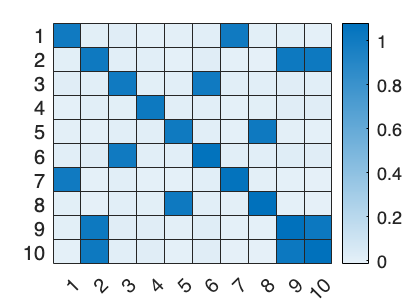

% Import data and convert to matrix
cov_10_asset = readmatrix('Kipnis_covMat.csv');
cov = (cov_10_asset); % Flip columns and transpose
% Display heatmap
heatmap(cov);

Apply our HRP function.

wgtHRP = Fn_HRP_estimate(cov_10_asset);

Output confirmed against R output as well as De Prado's results in his principle paper on HRP.

**MV for comparision **

% initiallising portfolio object, with mean, covar, lower, upper bound and
% budget constraints 
pMV = Portfolio('AssetCovar', assetCovar, 'AssetMean', mean(assetRetn_csv), 'lb', 0, 'ub', 1, 'budget', 1);
wgtMV = estimateFrontierLimits(pMV, 'min');

**Comparision Visualization**

Here you can visualize the resulting allocations from the two strategies. 

a = num2cell(1:nAssets);
labels = cellfun(@(x) num2str(x),a', 'UniformOutput', false);
ax1 = subplot(1,2,1);
pie(ax1,wgtHRP(wgtHRP>0),labels(wgtHRP>0))
title(ax1,'HRP Allocation','Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
pie(ax2,wgtMV(wgtMV>0),labels(wgtMV>0))
title(ax2,'Mean Variance Allocation' ,'Position', [-0.05, 1.6, 0]);
wgtTable = array2table([wgtHRP, wgtMV], 'VariableNames', {'HRP', 'MeanVariance'})

You can see that HRP produces a much more diversified allocation as compared to Mean-Variance framework. Next step, you can backtest the HRP strategy against others and extract their performance metrics. 

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)

- [https://en.wikipedia.org/wiki/Risk_parity](https://en.wikipedia.org/wiki/Risk_parity)